## EE634 HW3

## Kutay Ugurlu

### Q1

#### The HSI-RGB and RGB-HSI color conversion formulas are from [here.](https://www.had2know.org/technology/hsi-rgb-color-converter-equations.html#:~:text=Equations%20to%20Convert%20RGB%20Values%20to%20HSI%20Values&text=I%20%3D%20(R%20%2B%20G%20%2B%20B)%2F3.)

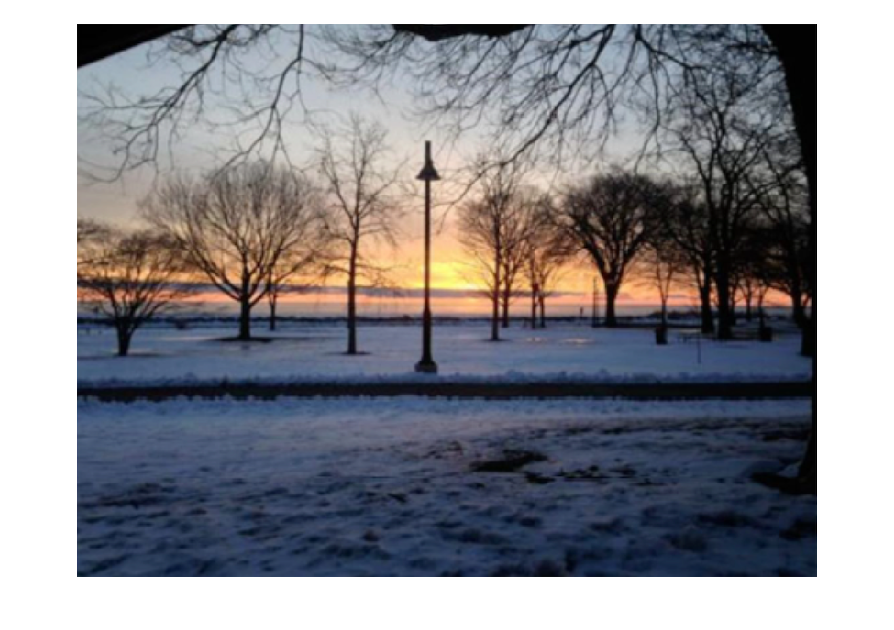

rgb = imread("colorImage.png");
figure
imshow(rgb)

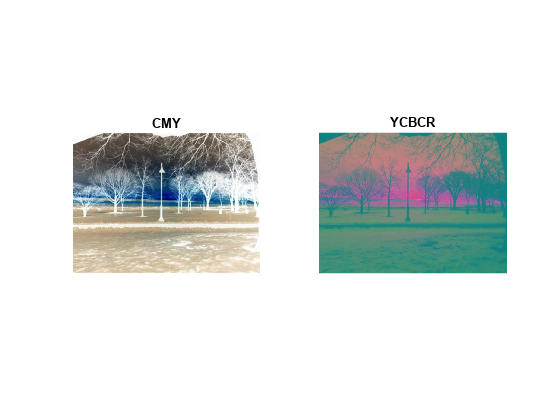

cmy = 255 - rgb; 
ycbcr = rgb2ycbcr(rgb);
figure
subplot(1,2,1)
imshow(cmy)
title("CMY")
subplot(1,2,2)
imshow(ycbcr)
title("YCBCR")

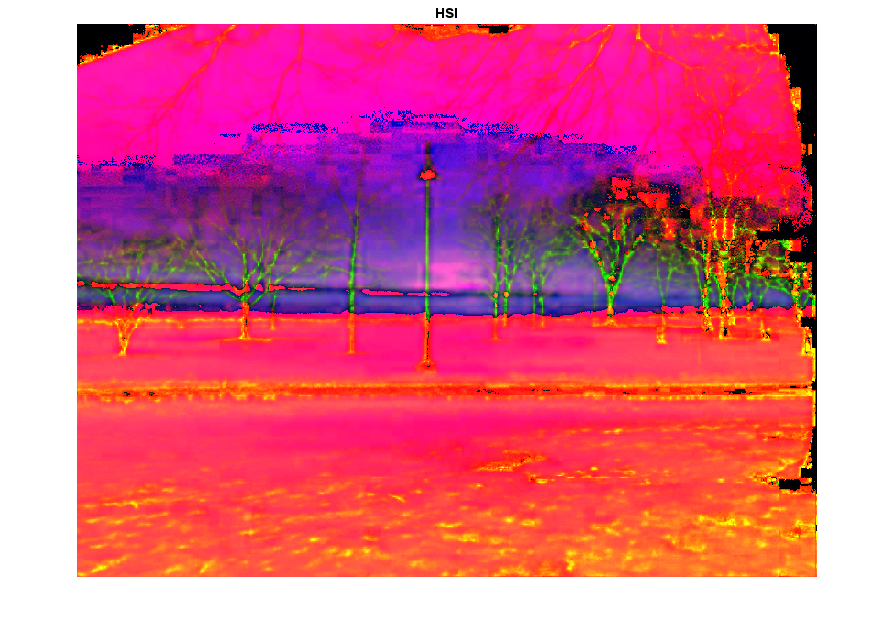

drgb = im2double(rgb);
R = drgb(:,:,1) ; G = drgb(:,:,2) ; B = drgb(:,:,3);
I = mean(drgb,3);
S = 1 - min(drgb,[],3)./I; S(I==0) = 0;
H = acos((R-0.5*G-0.5*B)./sqrt(R.^2+G.^2+B.^2-R.*G-R.*B-G.*B));
H(isnan(H)) = 0;
H(B>G) = 2*pi - H(B>G);
hsi = real(cat(3,H,S,I));
figure
imshow(hsi); title("HSI")

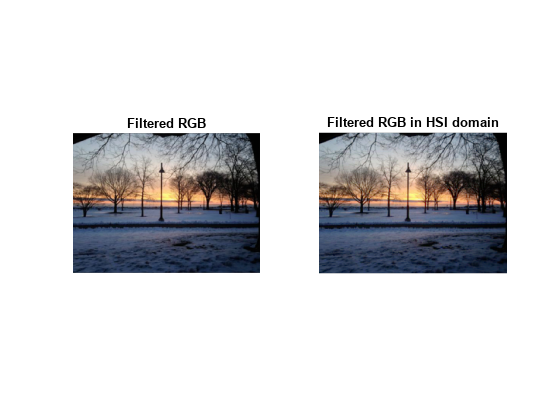

blur_filter = 1/25 * ones(5,5);
filt_r = conv2(R,blur_filter,"same");
filt_g = conv2(G,blur_filter,"same");
filt_b = conv2(B,blur_filter,"same");
filtered_RGB = cat(3,filt_r,filt_g,filt_b);

dhsi = double(hsi);
I = dhsi(:,:,end);
filt_I = conv2(I,blur_filter,"same");
dhsi(:,:,end) = filt_I;
filtered_HSI = dhsi;

H = filtered_HSI(:,:,1);
S = filtered_HSI(:,:,2);
I = filtered_HSI(:,:,3);

R_back = zeros(size(filt_I));
G_back = R_back;
B_back = G_back;

cond = (H==0 | H==2*pi);
R_back(cond) = I(cond) + 2*I(cond).*S(cond);
G_back(cond) = I(cond) - I(cond).*S(cond);
B_back(cond) = I(cond) - I(cond).*S(cond);

cond = (H>0 & H<2*pi/3);
R_back(cond) = I(cond) + I(cond).*S(cond).*cos(H(cond))./cos(pi/3-H(cond));
G_back(cond) = I(cond) + I(cond).*S(cond).*(1 - cos(H(cond))./cos(pi/3-H(cond)));
B_back(cond) = I(cond) - I(cond).*S(cond);

cond = (H==2*pi/3);
R_back(cond) = I(cond) - I(cond).*S(cond);
G_back(cond) = I(cond) + 2*I(cond).*S(cond);
B_back(cond) = I(cond) - I(cond).*S(cond);

cond = (H>2*pi/3 & H<4*pi/3);
R_back(cond) = I(cond) - I(cond).*S(cond);
G_back(cond) = I(cond) + I(cond).*S(cond).*cos(H(cond)-2*pi/3)./cos(pi-H(cond));
B_back(cond) = I(cond) + I(cond).*S(cond).*(1 - cos(H(cond)-2*pi/3)./cos(pi-H(cond)));

cond = (H==4*pi/3);
R_back(cond) = I(cond) - I(cond).*S(cond);
G_back(cond) = I(cond) - I(cond).*S(cond);
B_back(cond) = I(cond) + 2*I(cond).*S(cond);

cond = (H>4*pi/3 & H<2*pi);
R_back(cond) = I(cond) + I(cond).*S(cond).*(1 - cos(H(cond)-4*pi/3)./cos(5*pi/3-H(cond)));
G_back(cond) = I(cond) - I(cond).*S(cond);
B_back(cond) = I(cond) + I(cond).*S(cond).*cos(H(cond)-4*pi/3)./cos(5*pi/3-H(cond));

rgb_back = cat(3,R_back,G_back,B_back);
figure
subplot(1,2,1)
imshow(filtered_RGB)
title("Filtered RGB")
subplot(1,2,2)
imshow(rgb_back)
title("Filtered RGB in HSI domain")

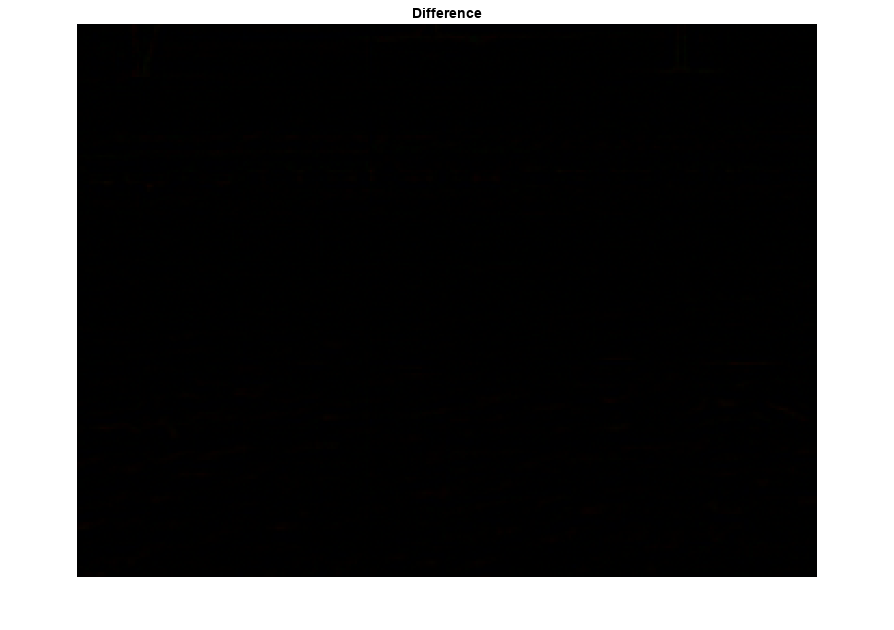

figure
imshow(filtered_RGB-rgb_back)
title('Difference')

### Q2